# Power Calculations

- *Electric Circuits Virtual Labs *

- *Author: Zekeriya Aliyazicioglu, Dennis Dahlquist*

## Introduction

In this section, AC power calculation is discussed. The definitions of instantaneous power p(t), average power P, reactive power Q, complex power S, apparent power |S|, and power factor pf are given. Power analysis is very important  in electric utilities, electronic, and communication systems. 

## Learning Objectives

Be able to 

- Explain the AC power concepts and relations

- Calculate instantaneous power, active power, reactive power, complex power, and power factor in a circuit

- Calculate  the load impedance required to deliver maximum real power to the load.

## Background Theory 

The instantaneous power of a circuit is defined as the product of the voltage and current, that is given as 

            
$$p(t)=v(t)i(t)$$


  Assume that the voltage and current are  sinusoids signals 

             $v(t)=V_m cos(\omega t+\theta_v)$, and    $i(t)=I_m cos(\omega t+\theta_i)$, 

Let’s shift both voltage and current by $\theta_i$

            $v(t)=V_m cos(\omega t+\theta_v-\theta_i)$, and    $i(t)=I_m cos(\omega t)$

Then, the instantaneous power can be written as

            
$$p(t)=v(t)i(t)=V_m I_m cos(\omega t+\theta_v-\theta_i)cos(\omega t)$$


Using the trigonometric identity, power is given as

            
$$p(t)=\frac{V_m I_m}{2} cos(\theta_v-\theta_i)+\frac{V_mI_m}{2}cos(2\omega t+\theta_v-\theta_i)$$


Let $\theta$ represents the difference of phases $\theta_v$ and $\theta_i$

                 
$$p(t)=\frac{V_m I_m}{2} cos(\theta)+\frac{V_mI_m}{2}cos(2\omega t+\theta)$$


The average power is defined as the average of the instantaneous power

                
$$P=\frac{1}{T} \int_0^Tp(t)dt$$


Since the second term of the instantaneous power is  periodic cosine wave, the average value is zero. Thus, the average power is given by

                  
$$P=\frac{V_m I_m}{2} cos(\theta)=\frac{V_m I_m}{\sqrt2 \sqrt2} cos(\theta)=V_{rms}I_{rms}cos(\theta)$$


The power factor (pf) is defined as

                    
$$pf=cos(\theta)$$


Using the trigonometric identity $cos(a+b)=cos(a)cos(b)-sin(a)sin(b)$, the instantaneous power p(t)  can be rewritten as

                 
$$p(t)=\frac{V_m I_m}{2} cos(\theta)+\frac{V_mI_m}{2}cos(\theta)cos(2\omega t)-\frac{V_mI_m}{2}sin( \theta)sin(2\omega t)$$


In this equation,

- the first term is constant,

- the 2nd and 3rd show that instantaneous power has twice frequency of the voltage or current.

- It has negative for some portion of cycle. That means, energy stored in the inductors or capacitors is now being extracted.

We can divide the instantaneous power (last equation) in three terms

            
$$p(t)=P+P cos(2\omega t)-Qsin(2\omega t)$$


where P is called the active, average power,or real power

                  $P=\frac{V_m I_m}{2} cos(\theta)$   [W]

Q is called the reactive power

                   $Q=\frac{V_m I_m}{2} sin(\theta)$  [VAR]

Complex power is given as the complex sum of real power and reactive power.

                   $S=P+jQ$  [VA]

The phasor for v(t) is $V=V_m \angle \theta_v$   and the phasor for i(t) is $I=I_m \angle \theta_i$

The complex power is defined as 

                    $S=\frac{1}{2}VI^*=\frac{1}{2} V_me^{j \theta_v} I_m e^{j \theta_i} =\frac{1}{2} V_m I_m e^{j(\theta_v- \theta_i)}=\frac{1}{2} V_m I_m e^{j\theta}$,   $S=\frac{1}{2} V_m I_m cos(\theta)+j \frac{1}{2}V_m I_m sin(\theta)$

The magnitude |S| of the complex power S is called the apparent power and given by

                   $|S|=\sqrt {P^2+Q^2}= \frac{V_mI_m}{2} = V_{rms}I_{rms}$  [VA]

The angle of the complex power is given by

                 $\angle S = \theta =tan^{-1} \Big ( \frac {Q}{P} \Big)$  [VA]

#### Example 1. Power Calculation

 Given  $v(t)=120cos(2\pi60t+60^ \circ)V$  and $i(t)=0.5cos(2\pi60t+30^ \circ)V$. Find the difference in phase angle, power factor, instantaneous power, average power, reactive power, complex power, and apparent power.

**Solution:**

Given

syms v(t) i(t)
f = 60; Vm = 120; theta_v = pi/3;
w=2*pi*f;
v(t) = Vm*cos(w*t+theta_v);
Im = 0.5;  theta_i = pi/6;
i(t) = Im*cos(w*t+theta_i);

The difference in phase angle is 

                 
$$\theta=\theta_v - \theta_i = 60^\circ  - 30^\circ=30^\circ$$


theta = theta_v - theta_i

theta = 0.5236

The power factor is

                  
$$pf= cos(\theta)=cos(30^\circ)$$


pf = cos(theta)

pf = 0.8660

The instantaneous power  is

              
$$p(t) = v(t)i(t) = \frac{V_m I_m}{2} cos(\theta)+\frac{V_mI_m}{2}cos(2\omega t+\theta)$$


syms p(t)
p(t) = (Vm*Im)/2*cos(theta)+(Vm*Im)/2*cos(2*w*t+theta)

$$p(t) = 30\,\cos\left(\frac{\pi }{6}+240\,\pi \,t\right)+15\,\sqrt{3}$$

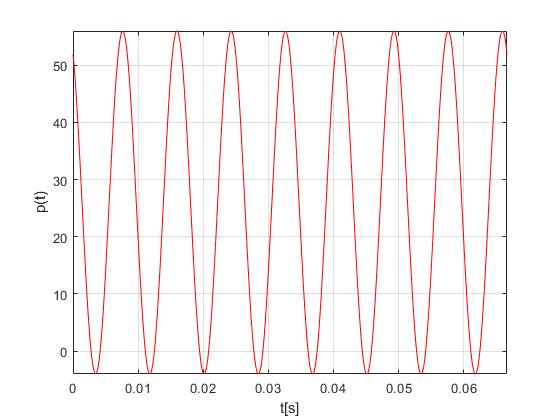

T = 1/f;
figure ()
fplot(p(t),[0 4*T],'r')
grid on; % grid minor
xlabel('t[s]'); ylabel('p(t)')

The average power is 

          
$$P=\frac{V_m I_m}{2} cos(\theta)$$


P=(Vm*Im)/2*cos(theta)

P = 25.9808

The reactive power is

             
$$Q=\frac{V_m I_m}{2} sin(\theta)$$


Q=(Vm*Im)/2*sin(theta)

Q = 15.0000

The complex power is given by

              
$$S=P+jQ$$
  

S = P+j*Q

S = 25.9808 + 15.0000i

The apparent power is given by

               
$$|S| = \sqrt {P^2+Q^2}$$
 

S_abs=abs(S)

S_abs = 30

#### Exercise 1. Power Calculation

 Given  $v(t)=60cos(2\pi60t+30^ \circ)V$  and $i(t)=2cos(2\pi60t-60^ \circ)V$. Find the difference in phase angle, power factor, instantaneous power, average power, reactive power, complex power, and apparent power.

**Solution Steps:**

Given

% syms v(t) i(t)
% f = 60; Vm = ; theta_v = ;
% w=2*pi*f;
% v(t) = ;
% Im = ;  theta_i = ;
% i(t) = ;

The difference in phase angle is 

% theta = 

The power factor is

% pf = 

The instantaneous power  is

% syms p(t)
% p(t) = 
% T = 1/f;
% figure ()
% fplot(p(t),[0 4*T],'r')
% grid on; % grid minor
% xlabel('t[s]'); ylabel('p(t)')

The average power is 

% P=

The reactive power is

% Q=

The complex power is given by

% S = 

The apparent power is given by

% S_abs=

#### Example 2. Power Calculation in AC Circuit

- Find the voltage $v_0(t)$, current $i(t)$ and instantaneous power $p(t)$ cross R and C  in the circuit below for $v_s(t)=100cos(2\pi60t) $. 

- Find the difference in phase angle, power factor, complex power, average power, reactive power, and apparent power.

- If source frequency changes to 100Hz. Recalculate the previous circuit values. 

            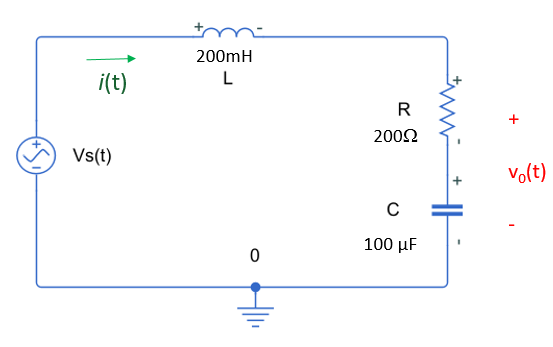

Given values in the circuit

syms v(t) i(t) p(t)
R = 200;
L = 200e-3;
C = 100e-6;
Vm = 100           % Amplitude value

Vm = 100

f = 100            % frequency

f = 100

theta = 0*pi/180;  % phase in radians

w = 2*pi*f;       % frequency in radians
T = 1/f           % period 

T = 0.0100

Plotting input voltage source 

% calculating and ploting vs(t)
vs(t) = Vm*cos(w*t+theta)

$$vs(t) = 100\,\cos\left(200\,\pi \,t\right)$$

figure ()
fplot(vs(t),[0.0 4*T],'r')

Conver input source in cartesian form

[Va, Vb] = pol2cart (theta, Vm);
Vs = complex(Va, Vb)

Vs = 1.0000e+02 + 0.0000e+00i

The circuit elements can be transformed into the impedances as

        $X_L=j \omega L$  and $X_C=\frac{1}{j \omega C}$

XL = j*w*L         % Impedance of Inductor 

XL = 0.0000e+00 + 1.2566e+02i

XC = 1/(j*w*C)     % Impedance of Capacitor 

XC = 0.0000 - 15.9155i

In the circuit, Impedance R and  $X_C$ are serial

        
$$Z_1=R+X_C$$


Z1 = R + XC

Z1 = 2.0000e+02 - 1.5915e+01i

Using voltage division to find $V_0$  in cartesian form  as

        
$$V_0=\frac{Z_1}{Z_1+X_L} V_s$$


V0 = Z1/(Z1+XL) * Vs

V0 = 73.5009 - 48.2907i

Finding voltage $v_0(t)$in time 

%Cartesian to Polar
[theta_v, V0m] = cart2pol(real(V0),imag(V0));
theta_vd = theta_v*180/pi;
v0(t) = V0m*cos(w*t+theta_vd);
digits(4)
v0(t) = vpa(v0(t))

$$v0(t) = 87.95\,\cos\left(628.3\,t-33.31\right)$$

 Ploting $v_0(t)$

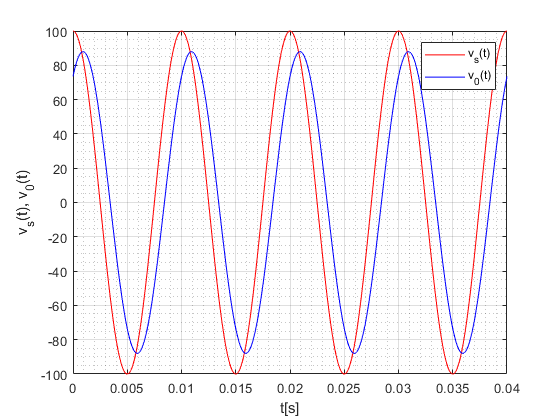

% ploting v0(t)
hold on
v0(t) = V0m*cos(w*t+theta_v);
fplot(v0(t),[0.0 4*T],'b')
grid on; grid minor
xlabel('t[s]'); ylabel('v_s(t), v_0(t)')
% axis([0 0.04 -Vm-2 Vm+2])
legend('v_s(t)', 'v_0(t)')

The current $I$  can be calculated using  impedance $Z_1$ and voltage $V_0$

             
$$I=\frac{V_0}{Z_1}$$


I = V0/Z1

I = 0.3843 - 0.2109i

Finding current $i(t)$in time

%Cartesian to Polar
[theta_i, Im] = cart2pol(real(I),imag(I));
theta_id = theta_i*180/pi;
i(t) = Im*cos(w*t+theta_id);
digits(4)
i(t) = vpa(i(t))

$$i(t) = 0.4383\,\cos\left(628.3\,t-28.76\right)$$

 Ploting i(t)

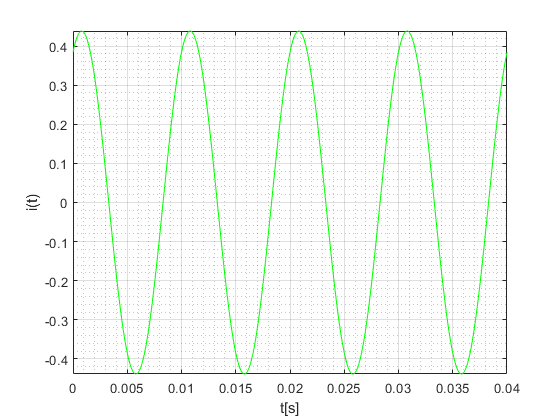

% ploting i(t)
figure()
i(t) = Im*cos(w*t+theta_i);
T = 1/f;
fplot(i(t),[0.0 4*T],'g')
grid on; grid minor
xlabel('t[s]'); ylabel('i(t)')

% axis([0 0.04 -Im-0.01 Im+0.01])

The difference in phase angle is 

                 
$$\theta=\theta_v - \theta_i $$


theta = angle(V0)-angle(I)

theta = -0.0794

The power factor is

                  
$$pf = cos(\theta)$$


pf = cos(theta)

pf = 0.9968

The instantaneous power  is

                  
$$p(t) = v_0(t)i(t) $$


p(t) = v0(t)*i(t);
p(t) =  simplify (p(t));
p(t)=vpa(p(t),4)

$$p(t) = 19.28\,\cos\left(1257.0\,t-1.083\right)+19.21$$

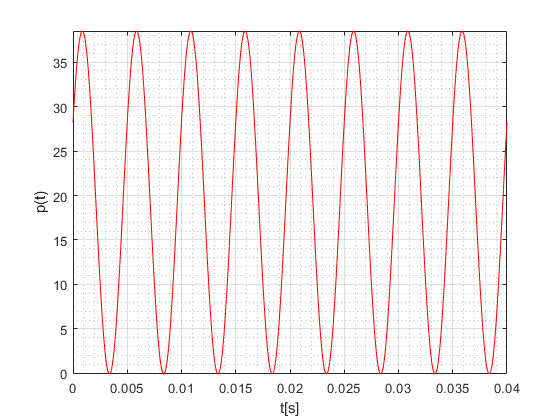

figure ()
fplot(p(t),[0 4*T],'r')
grid on;  grid minor
xlabel('t[s]'); ylabel('p(t)')

The complex power is given by

               
$$S=P+jQ=\frac{1}{2}V_0I^*$$
  

S = V0*conj(I)/2

S = 19.2143 - 1.5290i

The average (active) power is 

                  
$$P=\mathfrak{Re}(S)=S cos(\theta)$$


 P = real(S)

P = 19.2143

The reactive power is

               
$$Q=\mathfrak{Im}(S)=S sin(\theta)$$


Q=imag(S)

Q = -1.5290

The apparent power is given by

               
$$|S| = \sqrt {P^2+Q^2}$$
 

 S_abs=abs(S)

S_abs = 19.2750

Circuit can be simulated  in MATLAB Simulink [./Simulink\Example_2.slx](matlab:open('./Simulink\Example_2.slx'))

    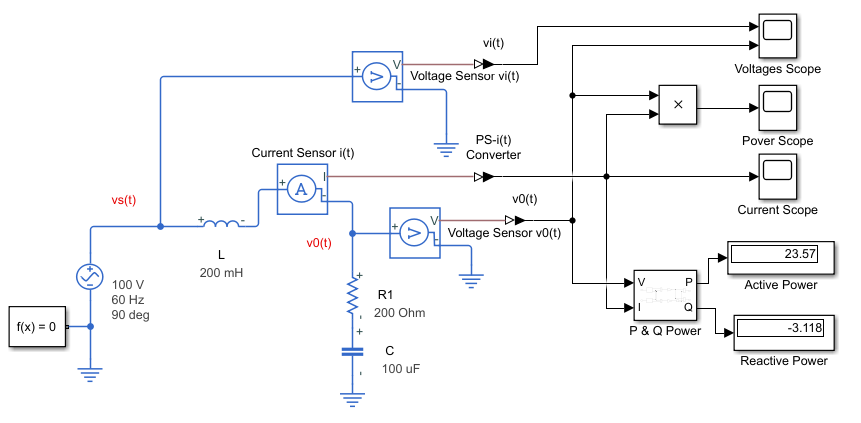

Voltages  $v_s(t)$and $v_0(t)$in the simulation are shown in the following figure

#### 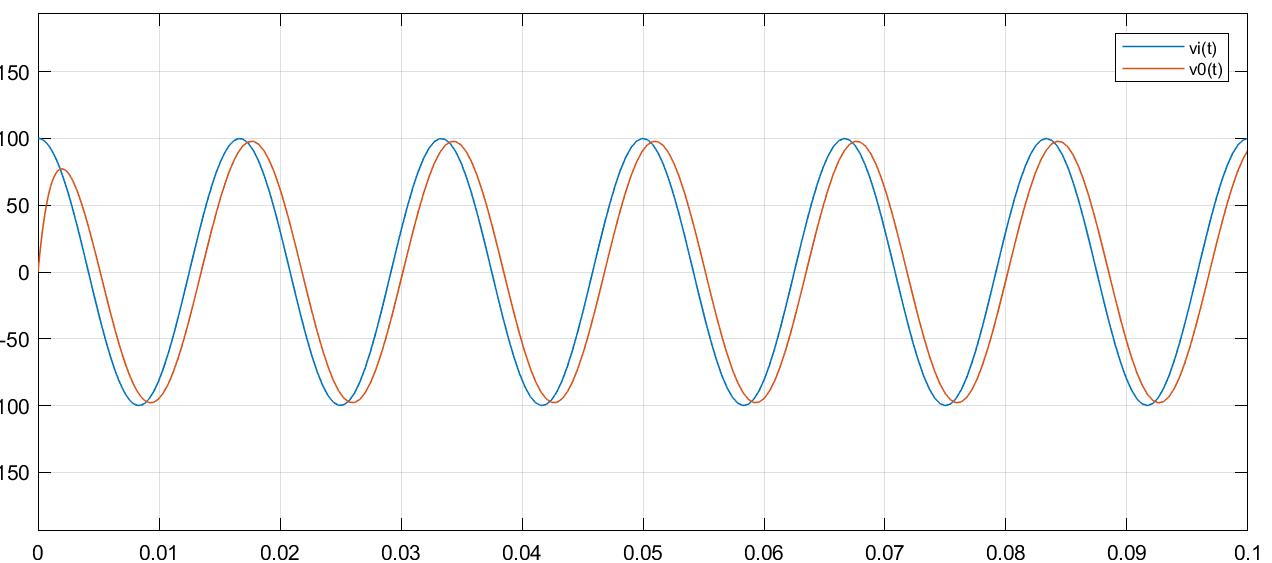

#### Current  $i(t)$in the simulation is shown in the following figure

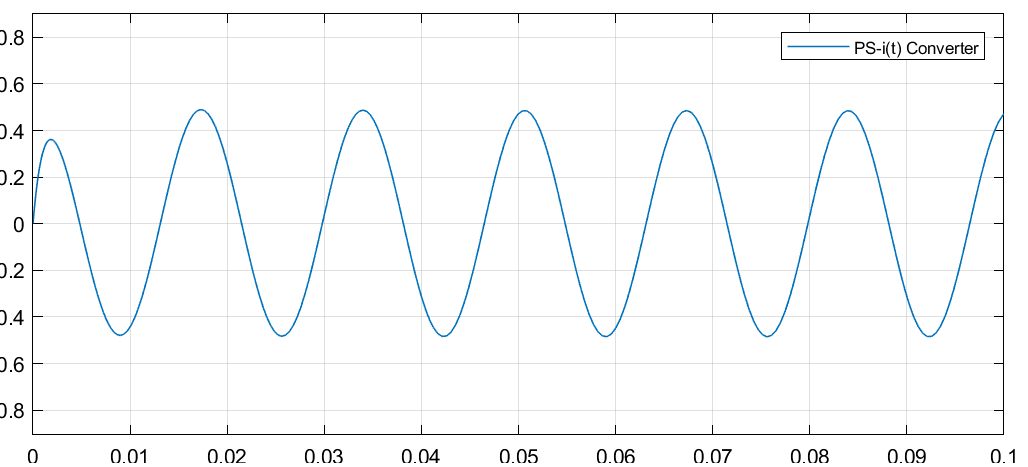

The instantaneous power  $p(t)$in the simulation is shown in the following figure

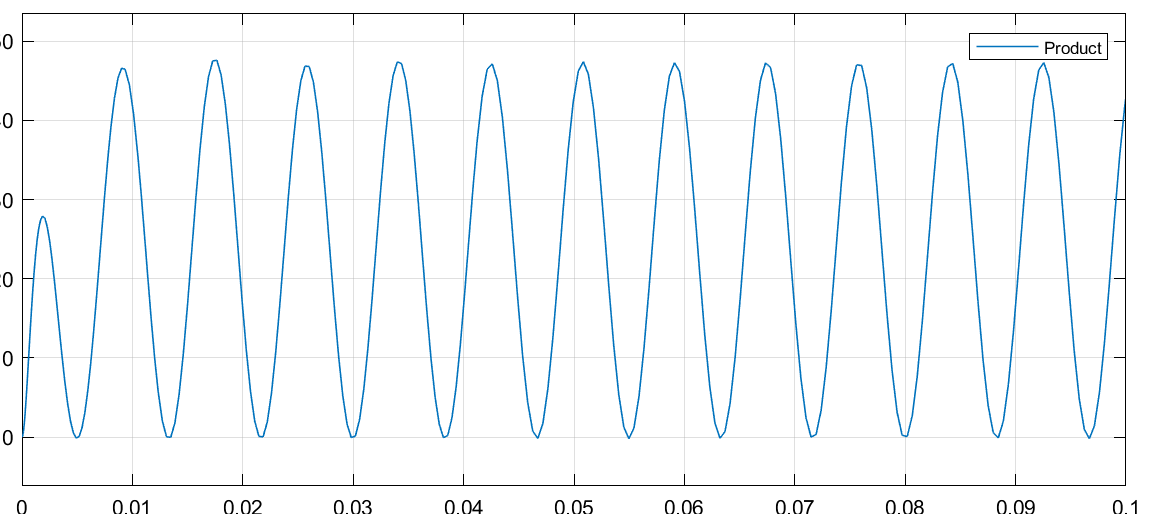

#### Exercise 2. Power Calculation in AC Circuit

- Find the voltage $v_0(t)$ and current $i(t)$ in the circuit below for $v_s(t)=120cos(2\pi60t) $. 

- Find  instantaneous power cross parellel R and L  in the circuit 

- Find the difference in phase angle, power factor, complex power, average power, reactive power, and apparent power.

- If source frequency changes to 100Hz. Recalculate the previous circuit values. 

            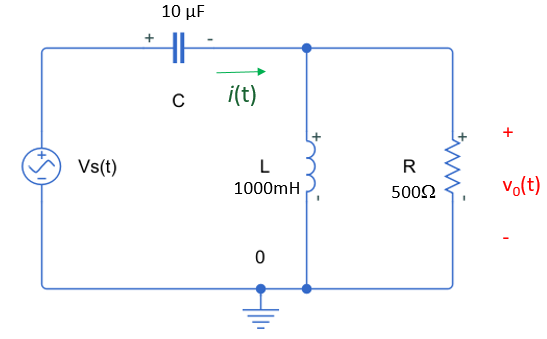

Given values in the circuit

% syms v(t) i(t) p(t)
% R = ;
% L = ;
% C = ;
% Vm =            % Amplitude value
% f = 100            % frequency
% theta = ;  % phase in radians
% 
% w = ;       % frequency in radians
% T =            % period 

Plotting input voltage source 

% % calculating and ploting vs(t)
% vs(t) =  
% figure ()
% fplot(vs(t),[0.0 4*T],'r')

Conver input source in cartesian form

% [Va, Vb] = pol2cart (theta, Vm);
% Vs = complex(Va, Vb)

Find the impedances of each circuit element

% XL =          % Impedance of Inductor 
% XC =          % Impedance of Capacitor 

In the circuit, find $Z_1$ impedance  for parallel  R and $X_L$ 

% Z1 =

Using voltage division to find $V_0$  in cartesian form 

% V0 = 

Find  voltage $v_0(t)$in time 

% %Cartesian to Polar
% [theta_v, V0m] = cart2pol(real(V0),imag(V0));
% theta_vd = theta_v*180/pi;
% v0(t) = V0m*cos(w*t+theta_vd);
% digits(4)
% v0(t) = vpa(v0(t))

 Ploting $v_0(t)$

% % ploting v0(t)
% hold on
% fplot(v0(t),[0.0 4*T],'b')
% grid on; grid minor
% xlabel('t[s]'); ylabel('v_s(t), v_0(t)')
% % axis([0 0.04 -Vm-2 Vm+2])
% legend('v_s(t)', 'v_0(t)')

Calculate  current $I$  

% I = 

Finding current $i(t)$in time

% %Cartesian to Polar
% [theta_i, Im] = cart2pol(real(I),imag(I));
% theta_id = theta_i*180/pi;
% i(t) = Im*cos(w*t+theta_id);
% digits(4)
% i(t) = vpa(i(t))

 Ploting i(t)

% % ploting i(t)
% figure()
% T = 1/f;
% fplot(i(t),[0.0 4*T],'g')
% grid on; grid minor
% xlabel('t[s]'); ylabel('i(t)')
% % axis([0 0.04 -Im-0.01 Im+0.01])

The difference in phase angle is 

% theta = 

Find the power factor

% pf = 

Write  instantaneous power  p(t) in time

% p(t) = 
% figure ()
% fplot(p(t),[0 4*T],'r')
% grid on;  grid minor
% xlabel('t[s]'); ylabel('p(t)')

Fid the complex power 

% S = 

The average (active) power is 

%  P = 

The reactive power is

% Q=

The apparent power is given by

%  S_abs=

Change the frequency of the source signal to 100Hz and recalculate the all values. 

Simulate  this exercise using MATLAB Simulink to chek your values

        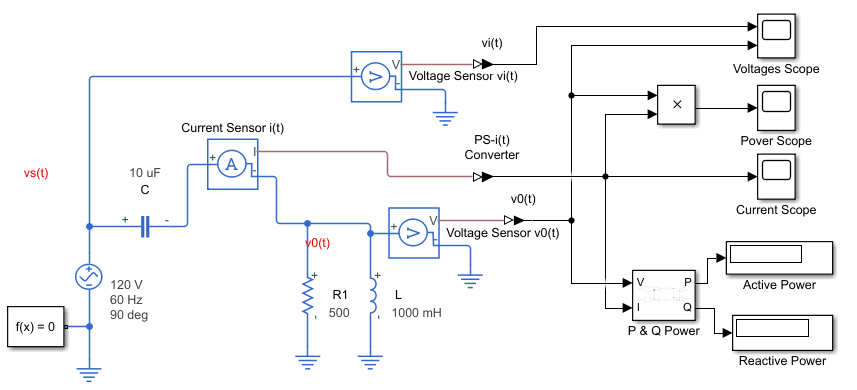

#### Example 3. Power Calculation  in AC circuit

Find the complex powers of all the elements in the circuit and verify the conservation of complexpowers.$v_s(t)=240cos(2\pi60t) $

        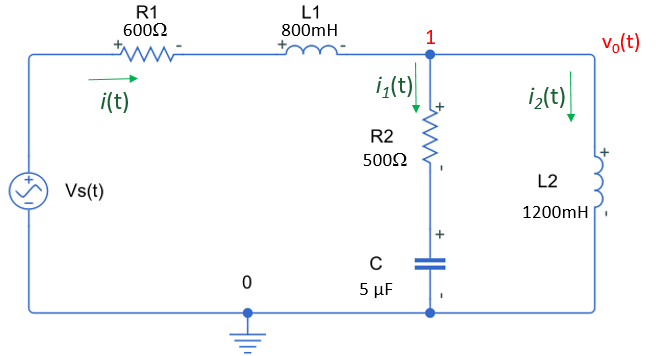       

Given values in the circuit

R1 = 600;
L1 = 800e-3;
R2 = 500;
C = 5e-6;
L2=1200e-3;
Vs = 240           % Amplitude value

Vs = 240

f = 60            % frequency

f = 60

theta = 0*pi/180;  % phase in radians

w = 2*pi*f;       % frequency in radians
T = 1/f           % period 

T = 0.0167

The circuit elements can be transformed into the impedances as

        $X_{L1}=j \omega L_1$  ,    $X_{L2}=j \omega L_2$   and $X_C=\frac{1}{j \omega C}$

XL1 = j*w*L1         % Impedance of Inductor L1

XL1 = 0.0000e+00 + 3.0159e+02i

XL2 = j*w*L2         % Impedance of Inductor L2

XL2 = 0.0000e+00 + 4.5239e+02i

XC = 1/(j*w*C)     % Impedance of Capacitor 

XC = 0.0000e+00 - 5.3052e+02i

In the circuit, Impedance $R_2+X_C$ is parallel to   $X_{L2}$ 

        $Z_1=R_2+X_C$ and   $Z_2=\frac{Z_1*X_{L2}}{Z_1+X_{L2}}$

Z1 = R2 + XC

Z1 = 5.0000e+02 - 5.3052e+02i

Z2=(Z1*XL2)/(Z1+XL2)

Z2 = 3.9956e+02 + 5.1482e+02i

Total Impedmance is

             
$$Z_t=R_1+X_{L1}+Z_2$$
 

Zt = R1 + XL1+Z2

Zt = 9.9956e+02 + 8.1641e+02i

The current flowing out of the voltage source is given by

                
$$I=\frac{Vs}{Z_t}$$


I=Vs/Zt

I = 0.1440 - 0.1176i

The voltage across the parallel connection of R2–C and L2 paths

        
$$V_0=Z_2I$$


V0 = Z2*I

V0 = 1.1811e+02 + 2.7145e+01i

abs(V0)

ans = 121.1865

angle(V0)*180/pi

ans = 12.9436

The current  I1 and I2 are given by

$I_1=\frac{V_0}{Z_1}$   and $I_2=\frac{V_0}{X_{L2}}$

I1 = V0/Z1

I1 = 0.0840 + 0.1434i

I2 = V0/XL2

I2 = 0.0600 - 0.2611i

abs(I2)

ans = 0.2679

angle(I2)*180/pi

ans = -77.0564

The voltage  are given by

$V_{R1}=R_1I$,    $V_{L1}=X_{L1}I$,    $V_{R2}=R_2I_1$, $V_{C}=X_CI_1$,    and   $V_{L2}=X_{L2}I_2$

VR1 = R1*I

VR1 = 86.4146 - 70.5814i

VL1 = XL1*I

VL1 = 35.4781 + 43.4367i

VR2 = R2*I1

VR2 = 42.0107 + 71.7194i

VC = XC*I1

VC = 76.0967 - 44.5747i

VL2 = XL2*I2

VL2 = 1.1811e+02 + 2.7145e+01i

The complex powers on all the elements of the circuit are

SR1 = VR1*conj(I)/2

SR1 = 10.3743

SL1 = VL1*conj(I)/2

SL1 = 0.0000 + 5.2147i

SR2 = VR2*conj(I1)/2

SR2 = 6.9086

SC = VC*conj(I1)/2

SC = 0.0000 - 7.3302i

SL2 = VL2*conj(I2)/2

SL2 = 0.0000 + 16.2318i

 The complex power of the voltage sourse is 

SVs=Vs*(conj(-I))/2

SVs = -17.2829 - 14.1163i

Circuit can be simulated  in MATLAB Simulink .[./Simulink\Example_3.slx](matlab:open('./Simulink\Example_3.slx'))

### 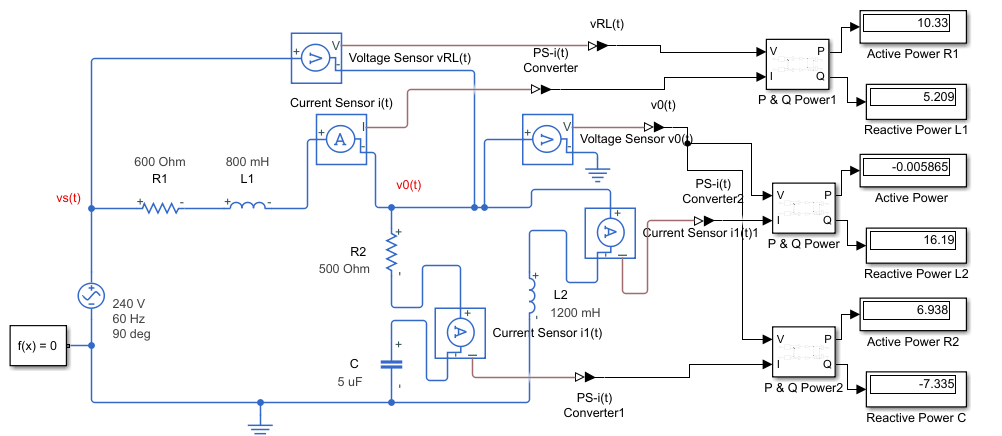

#### Exercise 3. Power Calculation in AC circuit

Find the complex powers of all the elements in the circuit and verify the conservation of complex powers for $v_{s1}(t)=240cos(2\pi60t) $ and $v_{s1}(t)=60cos(2\pi60t) $

    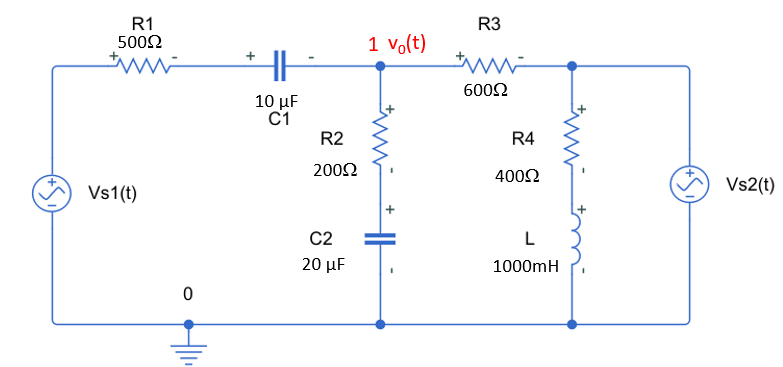

**Solution Steps:**

Given values in the circuit

% R1 =  ;
% C1 =  ;
% R2 =  ;
% C2 =  ;
% R3 =  :
% R4 =  ;
% L =   ;
% Vs1 =     ;           % Amplitude value
% theta1 = ;  % phase in radians
% f =   ;
% Vs2 =   ;
% theta2 = ;
% 
% w = 2*pi*f;       % frequency in radians
% T = 1/f           % period 

Transform the  circuit elements into the impedances 

% XC1 =          % Impedance of Capacitor C1
% XC2 =          % Impedance of Capacitor C2
% XL =           % Impedance of Inductor  

Apply KCL at unknown nodes 1

% V0 = solve (    )

Find the currents $I$, $I_1$, $I_2$,  and $I_3$

% I =
% I1 =
% I2 =
% I3 =

Find each element voltages  using the currents $I$, $I_1$, $I_2$,  and $I_3$

% VR1 = 
% VC1 = 
% VR2 = 
% VC2 = 
% VR3 = 
% VR4 =
% VL = 

Find the complex powers on all the elements of the circuit 

% SR1 = 
% SC1 = 
% SR2 = 
% SC2 = 
% SR3 = 
% SR4 =
% SL = 

Find the complex power of the voltage sourses

% SVs1 = 
% SVs2 =

Simulate  this exercise using MATLAB Simulink to chek your values. 

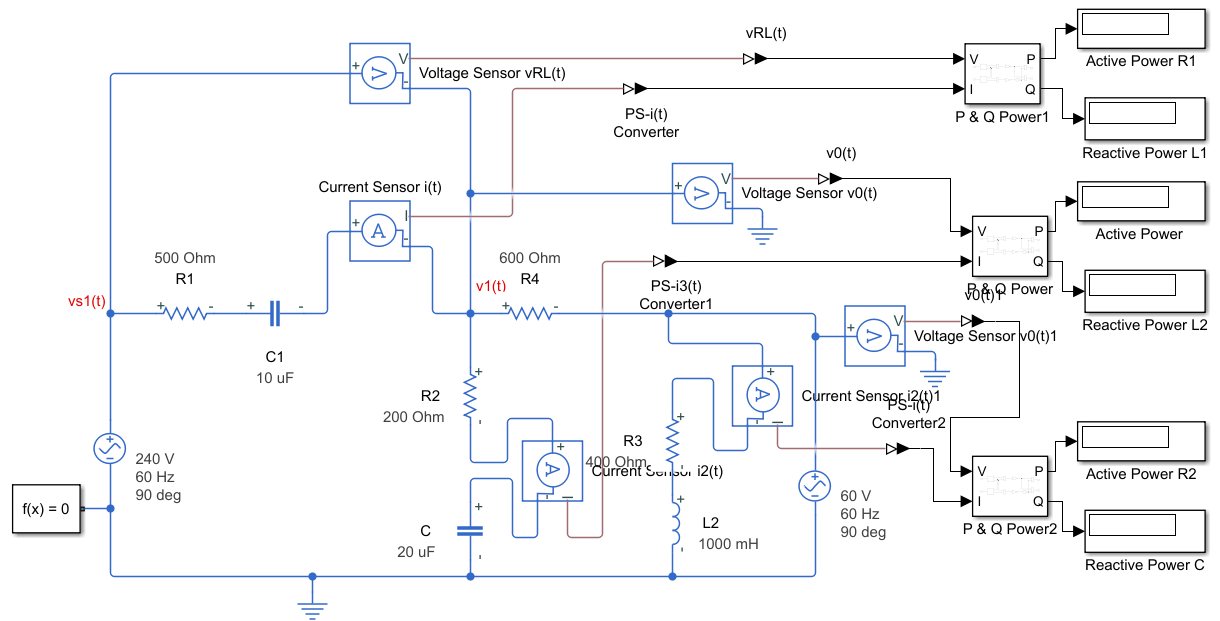

#### Maximum Power Transfer

Let the Thévenin equivalent impedance seen from the load toward the source be

            
$$Z_{Th}=R_{Th}+jX_{Th}$$


            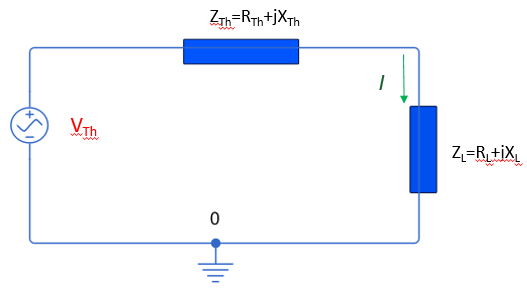

The current I through the circuit is given by

            
$$I=\frac{V_{Th}}{Z_{Th}+Z_L}=\frac{V_{Th}}{R_{Th}+jX_{Th}+R_L+jX_L}$$


The load impedance that maximizes the average power of the load is given by the complex conjugate of the Thévenin impedance

            
$$Z_L=Z^*_{Th}=R_{Th}-jX_{Th}$$


Therefore,

              
$$I=\frac{V_{Th}}{2R_{Th}}$$


The maximum average power of the load becomes

                
$$P_{max}=\frac{1}{2}|I|^2R_L=\frac{|V_{Th}|^2}{8R_{Th}$$


#### Example 4. Maximum Power Calculation in AC Circuit

- Find the load impedance $Z_L$ that will maximize the power transfer to the load for $v_s(t)=120cos(2\pi60t) $

- Find the maximum power absorbed by the load.

            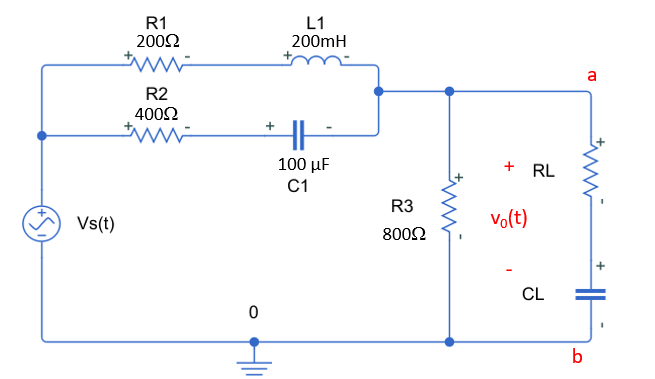       

Given values in the circuit

R1 = 200; R2 = 400; R3 = 800;
L1 = 200e-3; 
C1 = 100e-6; 
Vs = 120 ; theta_v = 0*pi/180;  %Voltage source amp and phase in radians         
f=60

f = 60

w = 2*pi*f;       % frequency

The circuit elements can be transformed into the impedances as

                $X_{L1}=j \omega L_1$   and $X_{C1}=\frac{1}{j \omega C_1}$

XL1 = j*w*L1         % Impedance of Inductor L1

XL1 = 0.0000 + 75.3982i

XC1 = 1/(j*w*C1)     % Impedance of Capacitor 

XC1 = 0.0000 - 26.5258i

The Thévenin equivalent impedance  $Z_{Th}$ is the equivalent impedance across a and b after deactivating the voltage source by short-circuiting it. 

                $Z_1=(R_1+X_{L1})||(R_2+X_{C1})=\frac{(R_1+X_{L1})*(R_2+X_{C1})}{(R_1+X_{L1})+(R_2+X_{C1})}$,  $Z_{Th}=Z_1||R_3=\frac{Z_1R_3}{Z_1+R_3}$ 

Z1 = (R1+XL1)*(R2+XC1)/((R1+XL1)+(R2+XC1))

Z1 = 1.3912e+02 + 3.0092e+01i

ZTh=(Z1*R3)/(Z1+R3)

ZTh = 1.1921e+02 + 2.1814e+01i

The Thévenin equivalent voltage between a and b is voltage $V_{Th}$.

                    
$$V_{Th}=\frac{R_3}{Z_1+R_3}V_s$$


VTh=R3/(Z1+R3)*Vs

VTh = 1.0212e+02 - 3.2722e+00i

abs(VTh)

ans = 102.1712

The load equivalent impedance  is given

                    
$$Z_L=Z^*_{Th}$$


ZL=conj(ZTh)

ZL = 1.1921e+02 - 2.1814e+01i

The maximum power delivered to the load is given by

                
$$P_{max}=\frac{1}{2}|I|^2R_L=\frac{|V_{Th}|^2}{8R_{Th}$$


Pmax=abs(VTh)^2/(8*real(ZL))

Pmax = 10.9461

Circuit can be simulated  in MATLAB Simulink  [./Simulink\Example_4.slx](matlab:open('./Simulink\Example_4.slx'))

### 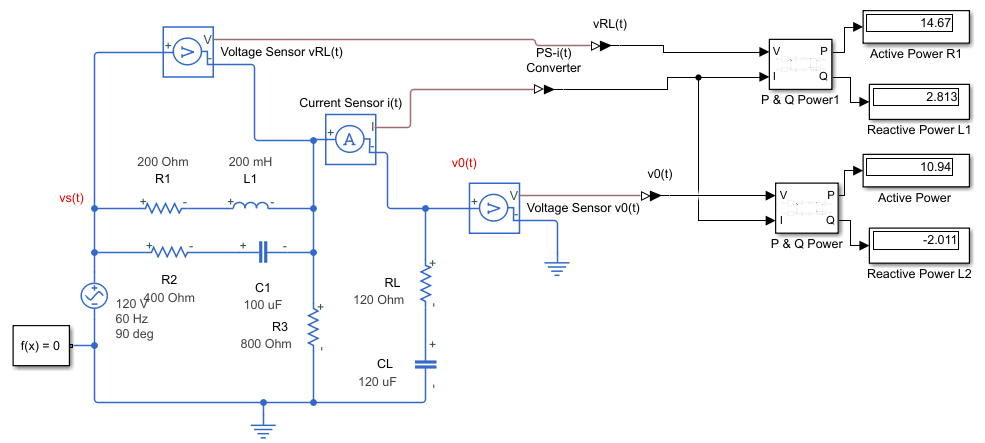

#### Exercise 4. Maximum Power Calculation in AC Circuit

- Find the load impedance $Z_L$ that will maximize the power transfer to the load for $v_s(t)=160cos(2\pi60t) $

- Find the maximum power absorbed by the load.

            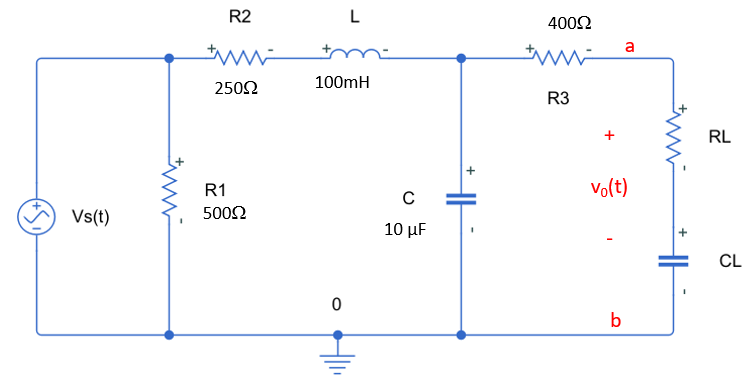       

Given values in the circuit

% R1 = ; R2 = ; R3 = ;
% L = ; 
% C1 = ; 
% Vs =  ; theta_v = ;  %Voltage source amp and phase in radians         
% f=
% w = 2*pi*f;       % frequency

The circuit elements L and C  can be transformed into the impedances as

% XL =          % Impedance of Inductor L
% XC =      % Impedance of Capacitor C

The Thévenin equivalent impedance  $Z_{Th}$ is the equivalent impedance across a and b after deactivating the voltage source by short-circuiting it. 

% Z1 = 
% ZTh=

The Thévenin equivalent voltage between a and b is voltage $V_{Th}$.

% VTh=

The load equivalent impedance  is given

% ZL=conj(ZTh)

The maximum power delivered to the load is given by

% Pmax= 

Using calculated load impenace value to simulate  this exercise using MATLAB Simulink to chek your max power values.

  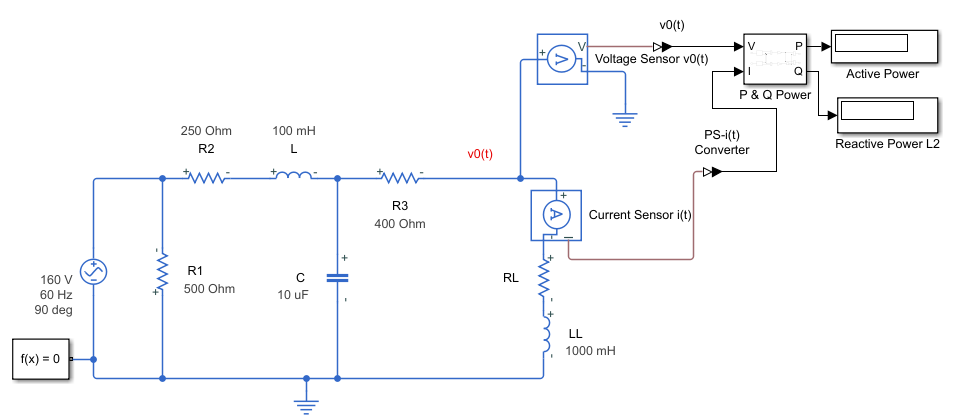

### References/Additional Info

***Electric Circuits***, James Kang, 1st ed. Cengage Learning, 2018